# Maximizing Solar Panel Output for a Fixed Area

In this project, we use MATLAB to formulate and solve an optimization problem. Given a fixed area, we determine the optimal tilt angle and aspect ratio of a solar panel that maximizes its total energy output.

## Breaking Down the Problem

Problem Statement Definition

Find the optimal tilt angle (θ) and aspect ratio (r) of a solar panel to maximize its total energy output. 

Requirements, Constraints, and Success Criteria 

**Requirements**: 

- Define the energy output formula E(θ, r) of a solar panel

- Use MATLAB's problem-based optimization workflow to maximize the energy output

- Make a 3D surface plot of E(θ, r) and display results

**Constraints**: 

- Area is fixed at 2 m²

- Tilt angle must be between 0° and 90°

- Aspect ratio must be between 0.5 and 4

**Success Criteria:**

- Numerical value for optimal tilt angle in degrees 

- Numerical value for optimal aspect ratio

- Numerical value for maximum energy output in simplified arbitrary units

- Visualization of E(θ, r)

Proposed Solution

Create a mathematical model that simulates the energy output of a solar panel and use MATLAB to test different combinations of the solar panel's tilt angle and aspect ratio. The code will automatically search for the optimal solutions using the Optimization Toolbox. 

Steps to Achieve Proposed Solution:

- **Energy Formula**: Create a function file that contains the energy function *EnergyObjective(θ, r),* which computes the energy output by taking into account the factors that affect its performance.

- **Set Up Optimization**: Define the objective function and create optimization variables with their constraints. 

- **Run the Solver:** Give MATLAB a starting guess and have it run solve( ) to find the optimal values. 

- **Graph and display:** Use surf( ) to graph the 3D surface plot and display the optimal values. 

Challenges Faced in the Process of Achieving the Solution

- **Optimization Default:** The optimization solver in MATLAB defaults to finding the minimum value of a function, so we had to figure out how to make it maximize the function instead. We used the MathWorks documentation to learn to add *ObjectiveSense = "maximize" *in the command.

- **Using the Function as the Objective Function: **Using our function as an objective function was not valid at first. We used the MathWorks documentation to learn how to turn the energy function into an optimization expression MATLAB could work with using the *fcn2optimexpr( )*. 

- **Angles (Degrees vs. Radians): **Standard *cos( )* in MATLAB expects radians, so we had to use *cosd( ) *to work directly with degrees. 

- **Vector Math**: Knowing when to use dot operators (like .* or .^) as sometimes not using them caused MATLAB grid calculations to fail. 

## Task 1: Define the Objective Function

The energy function is the objective function for this optimization problem. It calculates how much energy a solar panel produces based on its tilt angle (θ) in degrees and aspect ratio (r). The energy output has simplified units. 

Mathematical Model

Our energy equation is built by multiplying the main factors that influence the energy output of a solar panel. The energy is affected by the area of the solar panel, the sunlight intensity hitting the solar panel at different tilt angles, the energy efficiency of the solar panel, and the shape efficiency of the solar panel. 

**Area**: **A = 2 m² **

In this model, it is assumed that the panel area is fixed at 2 m². 

**Sun Intensity**:** I(θ) = 1000 * cos(θ - 45**°**) **

The sun intensity function represents the variation in sunlight intensity hitting the solar panel at different tilt angles. 1000 represents the maximum intensity, which occurs at 45° when the sun's rays are perpendicular to the solar panel's surface. The amount of intensity lost at different angles is represented by the cosine function. 

**Energy Efficiency Function:** **η(θ) = cos(θ - 30**°**) **

The energy efficiency function represents how efficiently a solar panel converts sunlight into electricity. In this model, the energy efficiency is dependent on its tilt angle. 30° is assumed to be the optimal angle for the panel's efficiency. 

**Aspect Ratio Efficiency: f(r) =  exp(−0.1 · (r − 1)²)**

The aspect ratio efficiency function models how the shape of the panel affects the energy output. The function is an exponentially decreasing function that represents the drop in efficiency as the aspect ratio differs from the optimal value. 

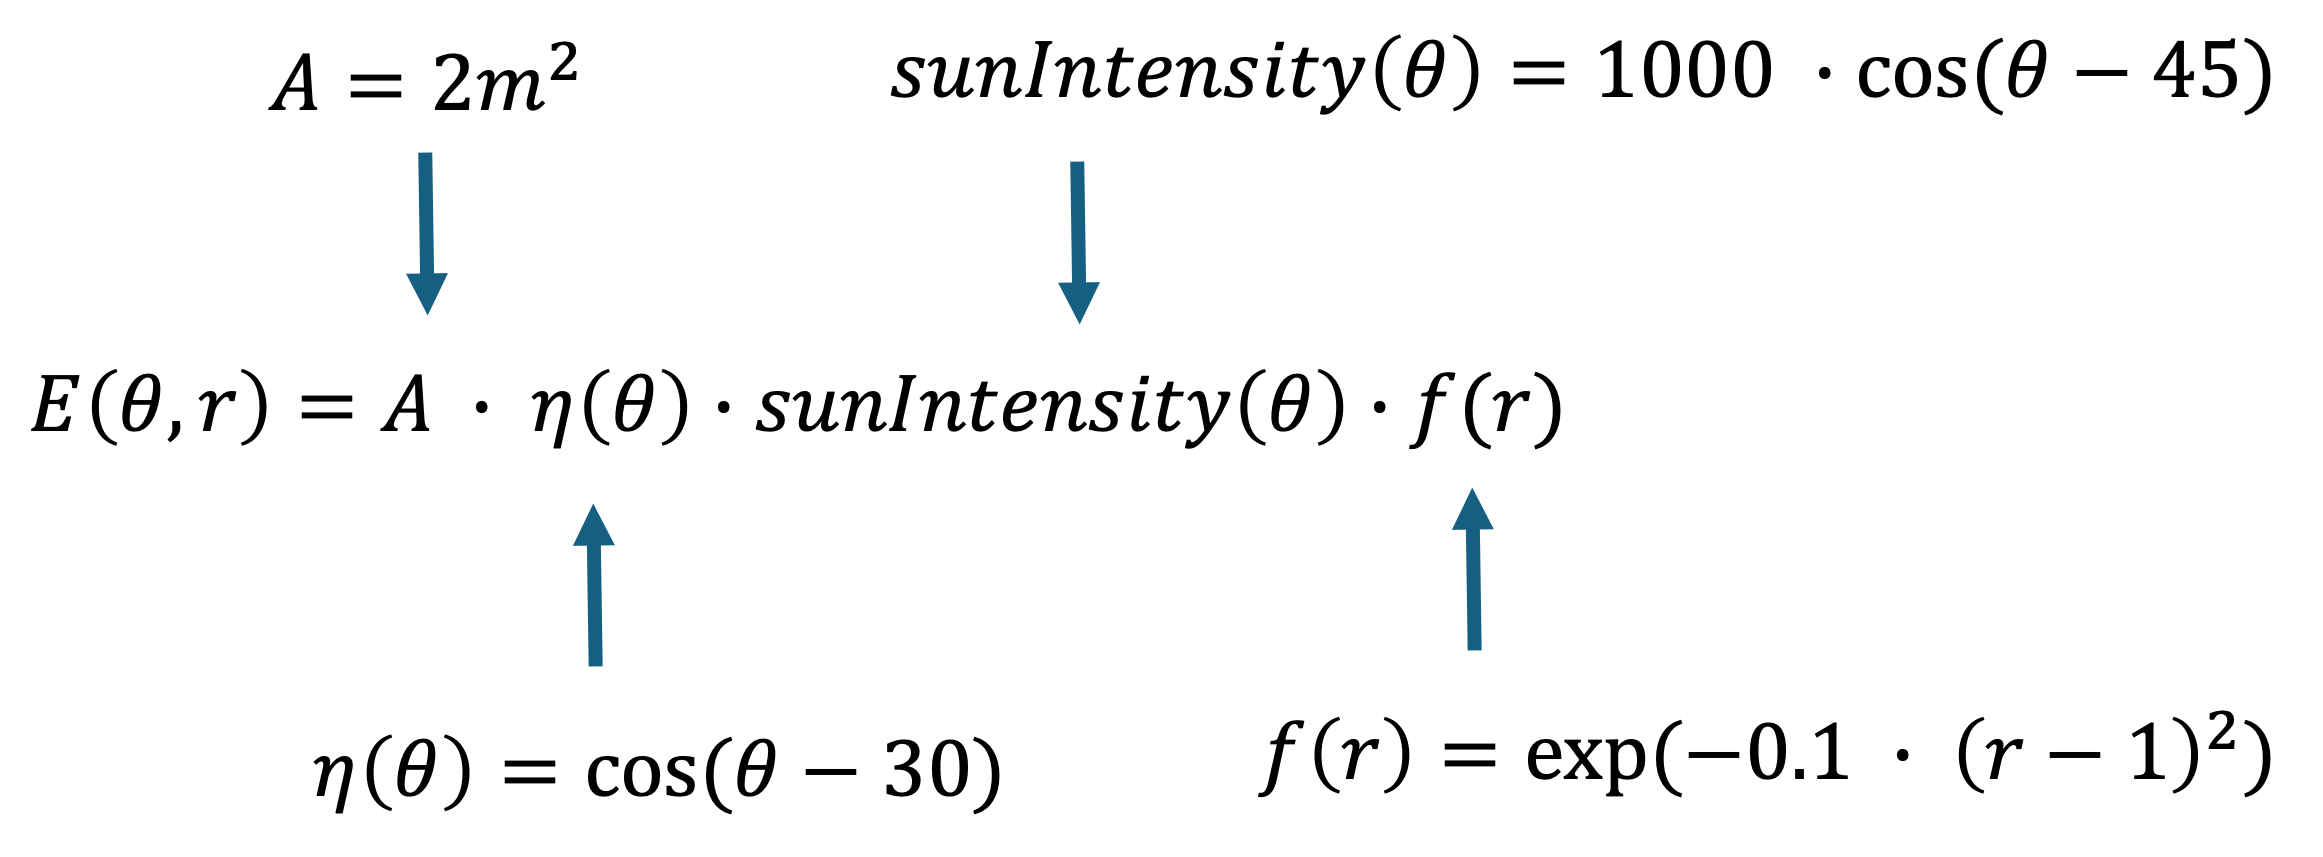

% --- Test Objective Function ---
% The objective function is defined in EnergyObjective.m

% Define sample test inputs
testTheta = 30; % Test angle in degrees
testR = 1; % Test aspect ratio (square panel)

% Compute test energy output
E_test = EnergyObjective(testTheta, testR);

% Display the test output
fprintf('Test Energy Output at theta = %d° and r = %d: %.2f\n', testTheta, testR, E_test);

Test Energy Output at theta = 30° and r = 1: 1931.85


## Task 2: Implement the Optimization Function

Use MATLAB's Optimization Toolbox to find the optimal tilt angle and aspect ratio that MAXIMIZE energy output. 

% Step 1. Create the optimization problem. We're telling MATLAB: "We want to MAXIMIZE 
% something." That "something" will be energy.

prob = optimproblem("Description", "Optimizing Solar Panel Energy Output", ObjectiveSense="maximize"); 

% Step 2. Define the optimization variables we can change in the problem
% These are the values MATLAB will try to optimize:
% - theta (tilt angle), must stay between 0 and 90 degrees
% - r (aspect ratio), must stay between 0.5 and 4

theta = optimvar("theta", LowerBound = 0, UpperBound = 90); 
r = optimvar("r", LowerBound = 0.5, UpperBound = 4);

% Step 3. Turn the energy function into an optimization probem MATLAB can
% work with. We should try to convert that function into an optimization
% expression

energy = fcn2optimexpr(@EnergyObjective, theta, r); 

% Step 4. Tell MATLAB what we want to maximize. We set our energy formula as the "objective" of the problem

prob.Objective = energy; 

% Step 5. Give MATLAB a starting point to begin the search
% Optimization needs a guess to start from:
     % Start searching from a tilt angle of ? degrees
     % Start searching from an aspect ratio of ?

initialGuess.theta = 30; 
initialGuess.r = 2; 

% Step 6. Solve the problem!

sol = solve(prob, initialGuess); 


Solving problem using fmincon.

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



% Storing Solutions 

maxTheta = sol.theta; 
maxR = sol.r; 
maxEnergy = evaluate(prob.Objective, sol); 


## Task 3: Output the Results

Use the appropriate plotting function to plot E(θ, r) and visualize the energy surface. Print the optimal tilt angle and aspect ratio, and corresponding energy output.

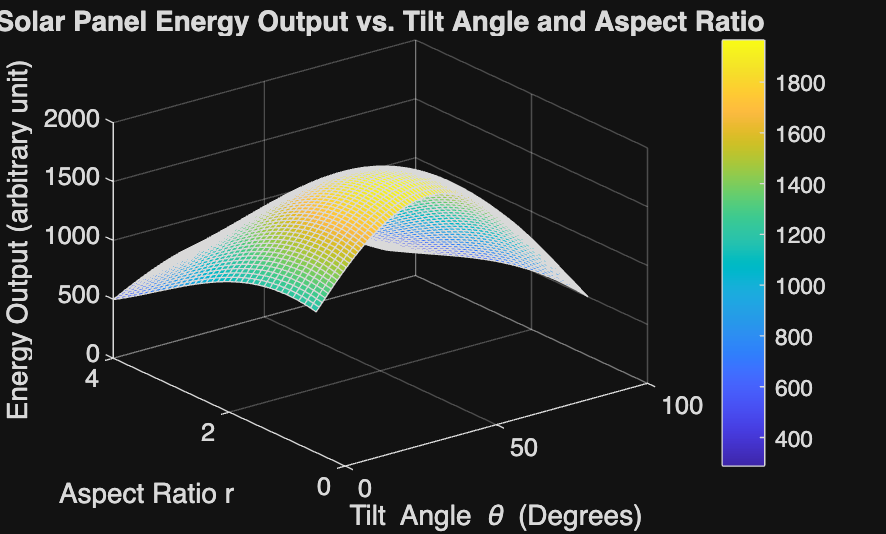

% Step 1: Make a bunch of points for the x and y axis meshgrid
% The step for the angle is 1, the step for ratio is 0.1
% Keeping theta and r within the constraints specified in the problem:
% 0 <= theta <= 90 and 0.5 <= r <= 4

[theta_grid, r_grid] = meshgrid(0:1:90, 0.5:0.1:4);

% Step 2: Calculate energy for every point on the meshgrid using element-wise operations
% We call the EnergyObjective function created in Task 1 to evaluate every coordinate pair

E_grid = EnergyObjective(theta_grid, r_grid);

% Step 3: Draw the 3d graph using the "surf" function
% Open a new figure window and generate the 3D surface plot

figure;
surf(theta_grid, r_grid, E_grid);

% Step 4: Label everything on the surf plot (title, axes, etc)

title('Solar Panel Energy Output vs. Tilt Angle and Aspect Ratio');
xlabel('Tilt Angle \theta (Degrees)');
ylabel('Aspect Ratio r');
zlabel('Energy Output (arbitrary unit)');

colorbar; % Adds a color scale bar for quick visual reference of energy values


% Step 5: Print the optimal tilt angle and aspect ratio, and corresponding
% energy output to the command window

fprintf("Optimal tilt angle: %0.2f degrees \n", maxTheta); 

Optimal tilt angle: 37.50 degrees 


fprintf("Optimal aspect ratio: %0.2f \n", maxR); 

Optimal aspect ratio: 1.00 


fprintf("Corresponding maximum output energy: %0.2f a.u.\n", maxEnergy); 

Corresponding maximum output energy: 1965.93 a.u.


## Interpretation of Results

Interpretation of physical/engineering meaning:

**Best Aspect Ratio ( r = 1.0 ): **The aspect ratio function f(r) =  exp(−0.1 · (r − 1)²) gives its highest output when r = 1. This means a square panel gives the best efficiency, while panels that are too long or wide lose performance. 

**Best Tilt Angle ( θ = 37.5**°** ): **The angle balances two different factors: panel efficiency (peaks at 30°) and sunlight intensity (peaks at 45°). The optimal angle is right in the middle: (30° + 45°)/2 = 37.5°. This angle balances high solar irradiance and effective sunlight absorbtion.

**Maximum Energy Output ( E = 1965.93 ): **Evaluating the formula at a tilt angle of 37.5° and an aspect ratio of 1.0 yields the highest achievable energy output for a fixed 2 m² panel under these conditions.

Limitations of work

**Sun Intensity Function: **The math assumes the sun stays frozen at a 45° angle all day. In reality, the sun moves across the sky throughout the day and changes position across different seasons.  

**Energy Efficiency Function: **The math assumes that efficiency is only dependent on the tilt angle. In reality, it is dependent on other factors such as panel material, cell temperature, and other envionrmental factors such as wind and shadows from trees and nearby buildings. 

**Aspect Ratio Function: **The aspect ratio function is simplified and assumes that a square panel is the most efficient at r = 1. 

Practical next steps

Practical next steps include modifying the energy formula to account for more enivornmental factors and make it more representative of realistic solar panels. This can incude updating the MATLAB code to calculate energy production over a full 24-hour day as the sun moves, rather than using a single static angle. In addition, we can Include wind effects, cell temperatures, outdoor temperatures, and shading into the MATLAB optimization setup. Lastly, we can use real solar panel effects on shape efficiency to develop the aspectc ratio efficiency function more accurately. 